# PRÁCTICA 8: Segmentación de Imágenes - optativa fusibles

## Enunciado

Realice un programa que admita una imagen de la carpeta .\Fuse  (de la 00 a la 20) y que determine de forma automática si el fusible es defectuoso o no.

#### Imágenes de fusibles

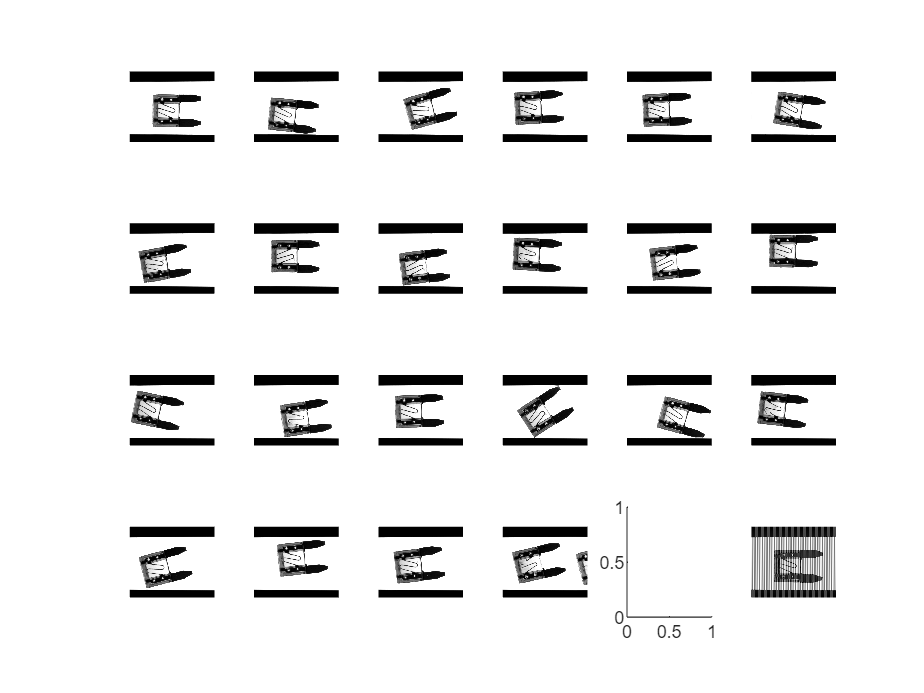

% pwd
figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        imshow(img);
    end
end

## Solución

### 1.- Preparación de pruebas

#### Vector de resultados esperados

Examinando la imagen definimos un vector para indicar el estado observado de cada uno de los fusibles

- 1: el fusible está bien

- 0: el fusible está roto

- -1: el fusible no existe

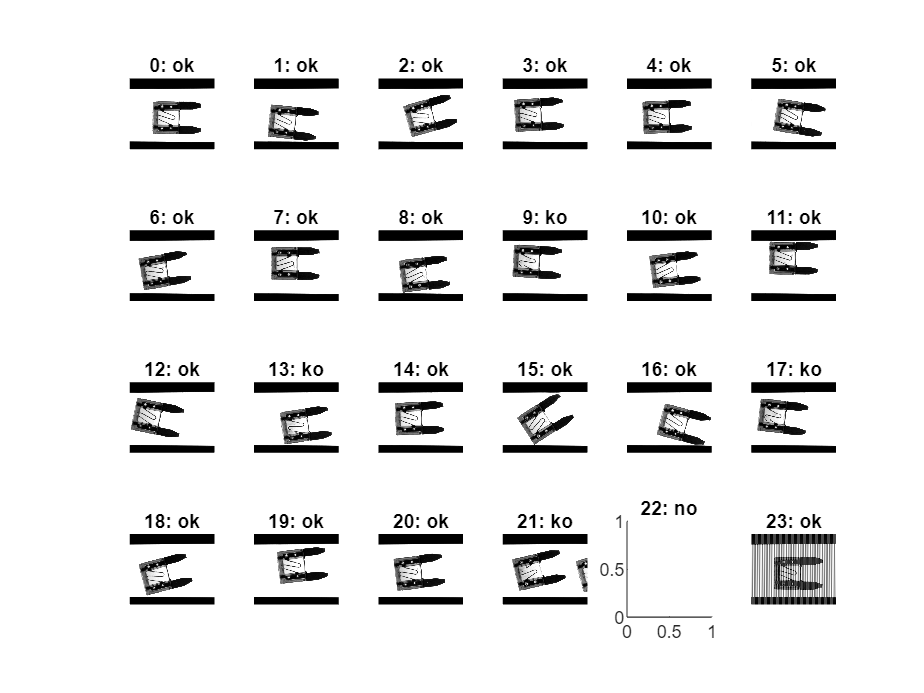

estados = [1 1 1 1 1 1   1 1 1 2 1 1   1 2 1 1 1 2   1 1 1 2 3 1];
titulos = ['ok';'ko';'no'];
figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        imshow(img);
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));     
end

#### Imagen de prueba

Este código permite elegir la imagen sobre la que vamos a realizar pruebas

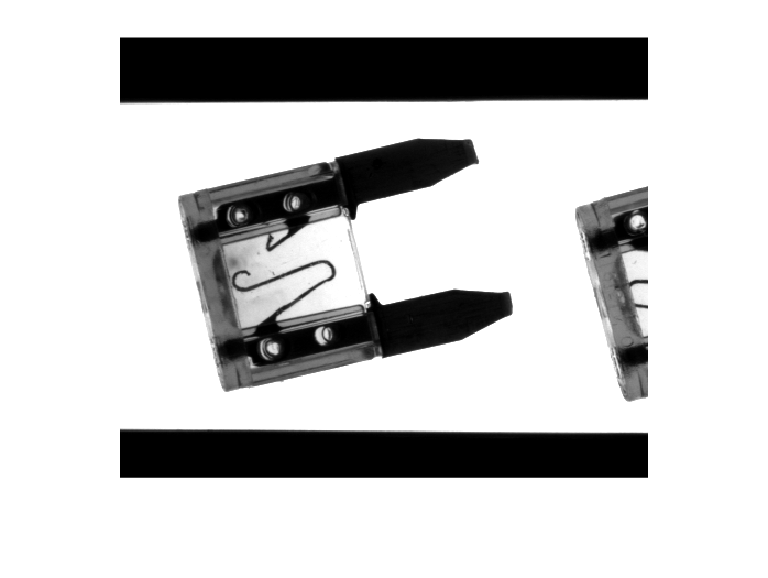

i = 21;
img21 = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
figure;
imshow(img21);

### 2.- Aplicación de regiones de interés

Lo primero que hacemos es descartar la parte superior e inferior de la imagen (cinta transportadora); para ello utilizamos la imagen 21 que tiene dos piezas sobre la cinta

% help imcrop
%figure
%imshow(img)
%[J,ROI] = imcrop(img21);

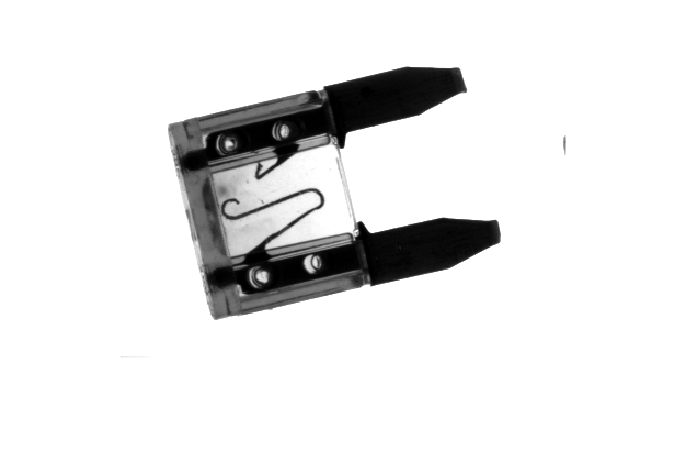

ROI = [10.51 65.51 405.98 290.98];
figure;
imshow(imcrop(img21, ROI));

Comprobamos que la ROI está bien definida para todas las imágenes

- En la imagen 16 se está truncando la parte derecha del fusible pero esto no debería ser un problema

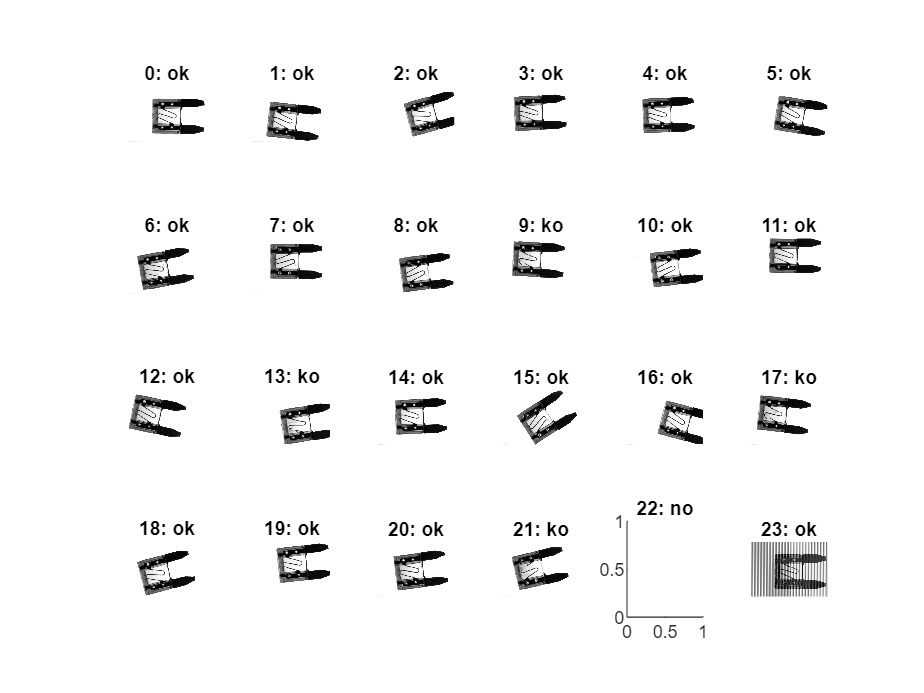

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        img = imcrop(img, ROI);
        imshow(img);
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));
end

### 3. Aplicación de filtado de ruido frecuencial

La imagen 23 tiene ruido frecuencial que hay que eliminar

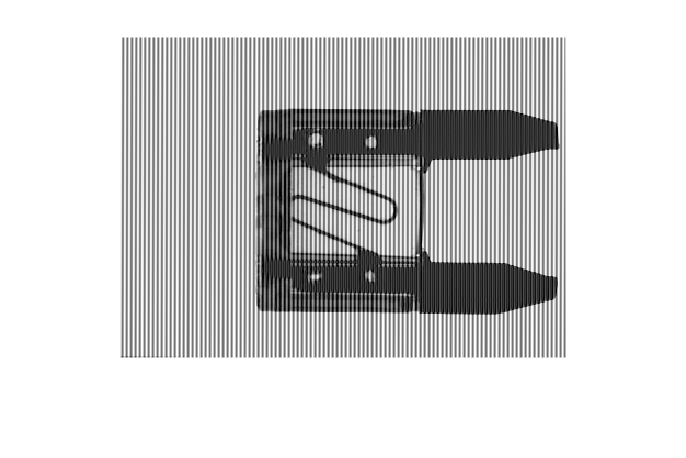

i = 23;
img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
imgc = imcrop(img, ROI);
figure;
imshow(imgc);

Para ello realizamos el análisis de Fourier de la imagen

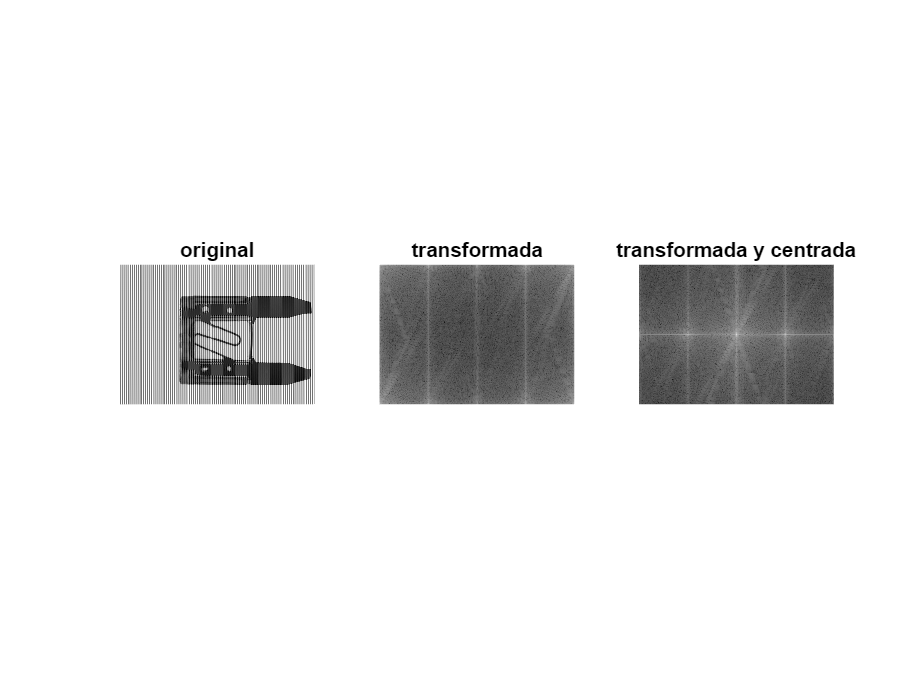

figure
subplot(1,3,1); imshow(imgc);title("original");
subplot(1,3,2); imshow(30*log10(1+abs(fft2(imgc)))/255);title("transformada");
subplot(1,3,3); imshow(30*log10(1+abs(fftshift(fft2(imgc))))/255);title("transformada y centrada")

Comprobamos las frecuencias que generan el ruido

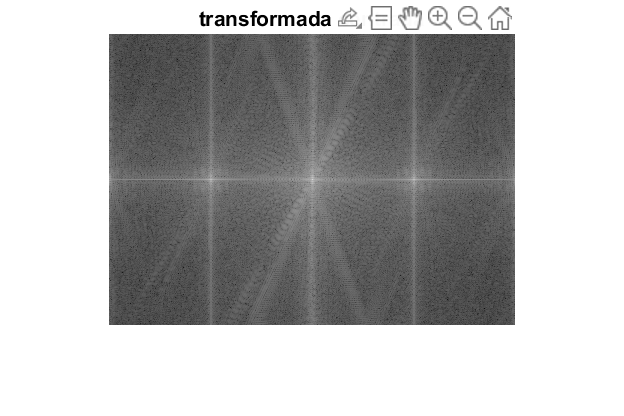

figure;
imshow(30*log10(1+abs(fftshift(fft2(imgc))))/255);title("transformada centrada");
[x,y] = ginput(3);

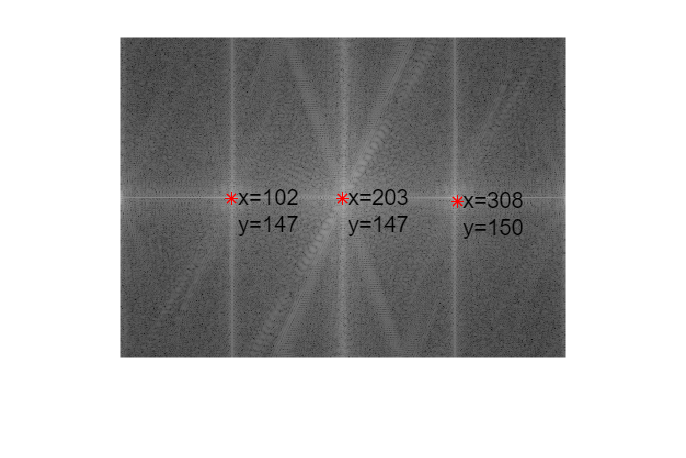

figure;
imshow(30*log10(1+abs(fftshift(fft2(imgc))))/255);
hold on;
plot(x, y, 'r*');
for i=1:3
    text(x(i),y(i)+10, sprintf(" x=%0.0f\n y=%0.0f",x(i),y(i)))
end

Y diseñamos un filtro paso bajo que elimine las frecuencias altas

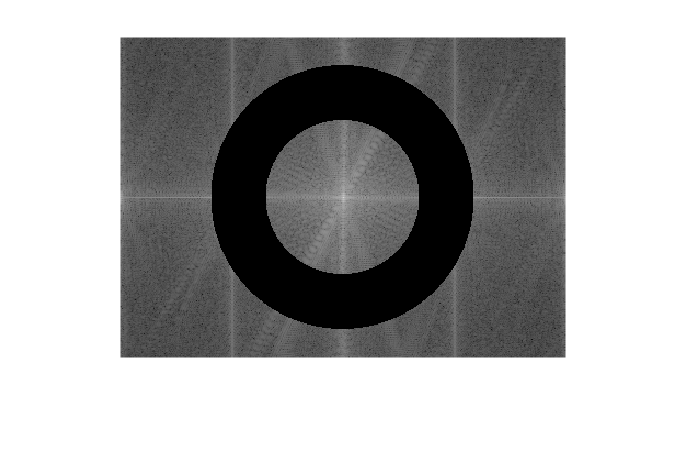

dmin = 70; % con 50 la imagen 15 pierde el puente de unión
dmax =120;
n = 1; % orden del filtro;
[tamx,tamy] = size(imgc); % Tamaño de la imagen
[xx,yy] = meshgrid(1:tamx,1:tamy);

%d = sqrt((xx-tamx/2).^2+(yy-tamy/2).^2); % Distancia al centro
ILPF = ((d < dmin)|(d>dmax))';
%ILPF = (((xx < 145)|(xx > 150))&((yy<95)|((yy>100)&(yy<305))|(yy>310)))';
figure
imshow(ILPF.*(30*log10(1+abs(fftshift(fft2(imgc))))/255));

Comprobamos que el filtro funciona correctamente en la imagen con ruido

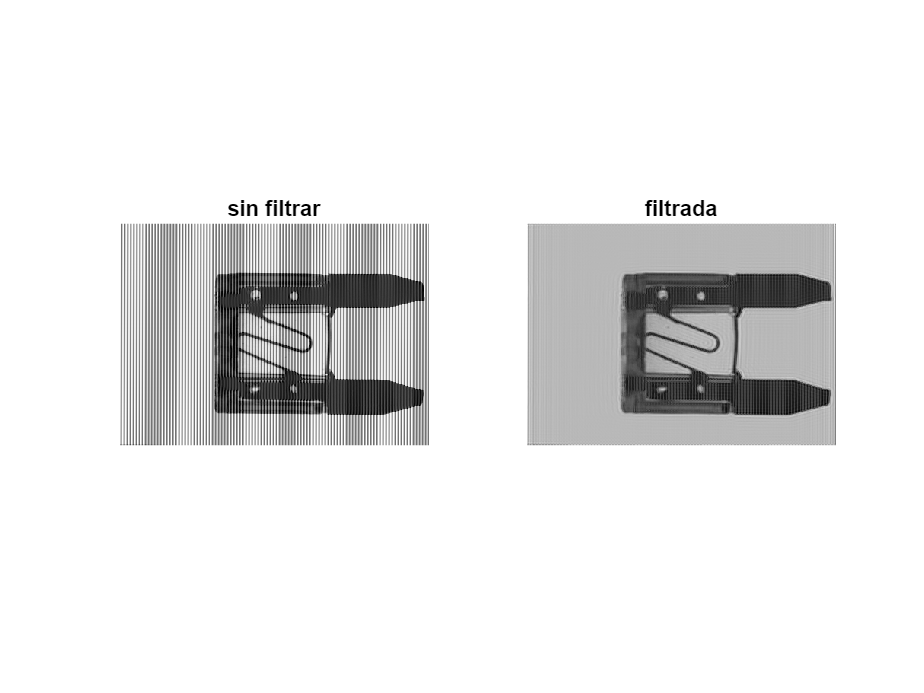

imgt = fft2(imgc);
imgf = real(ifft2(imgt .* fftshift(ILPF))/255);
figure;
subplot(1,2,1); imshow(imgc);title("sin filtrar");
subplot(1,2,2); imshow(imgf);title("filtrada");

Finalmente aplicamos el filtro a todas las imágenes para comprobar que no tiene ningún impacto negativo en el resto

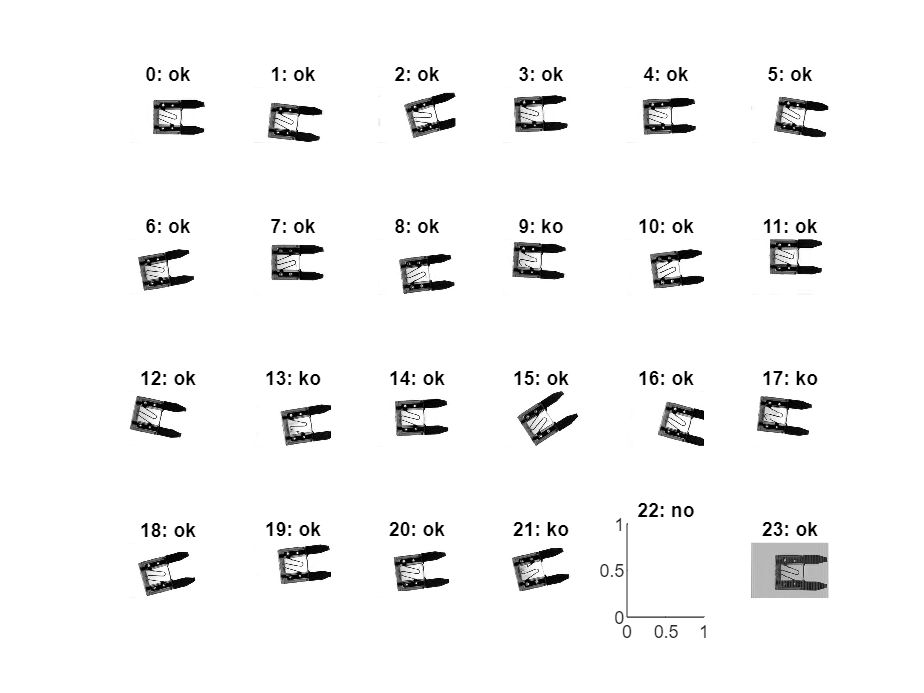

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        img = imcrop(img, ROI);
        imgf = real(ifft2(fft2(img) .* fftshift(ILPF))/255);
        imshow(imgf);
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));
end

### 4 Aplicación de binarización

Binarizamos las imágenes y observamos que hay muchos detalles que dificultan extraer descriptores (p. ej., imágenes 7, 8, 10, 15)

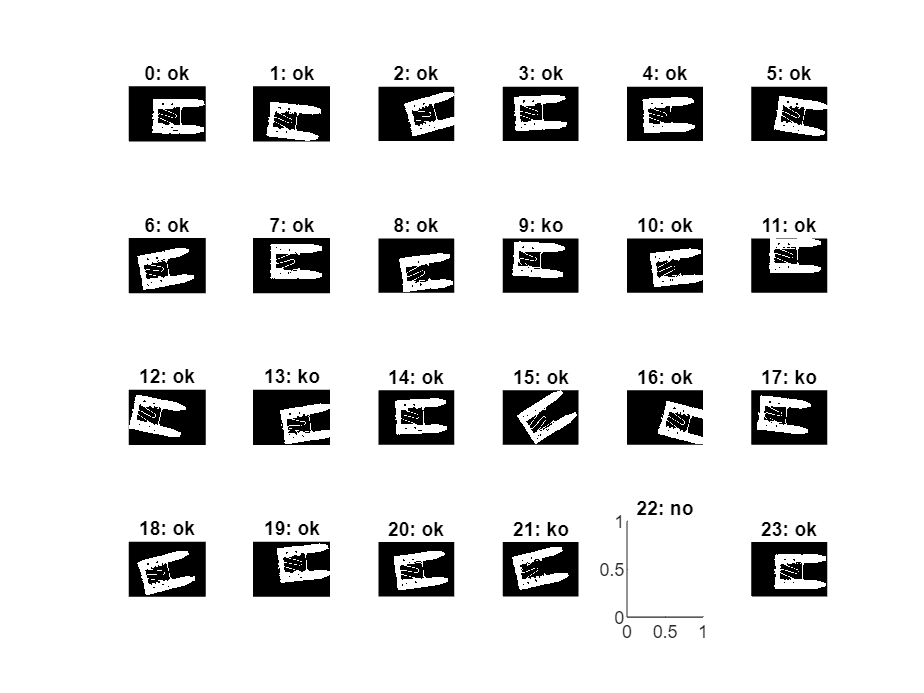

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        imgc = imcrop(img, ROI);
        imgf = real(ifft2(fft2(imgc) .* fftshift(ILPF))/255);
        imshow(1-imbinarize(imgf));
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));
end

Probamos con una binarización adaptativa y comprobmos que el detalle ya no se pierde

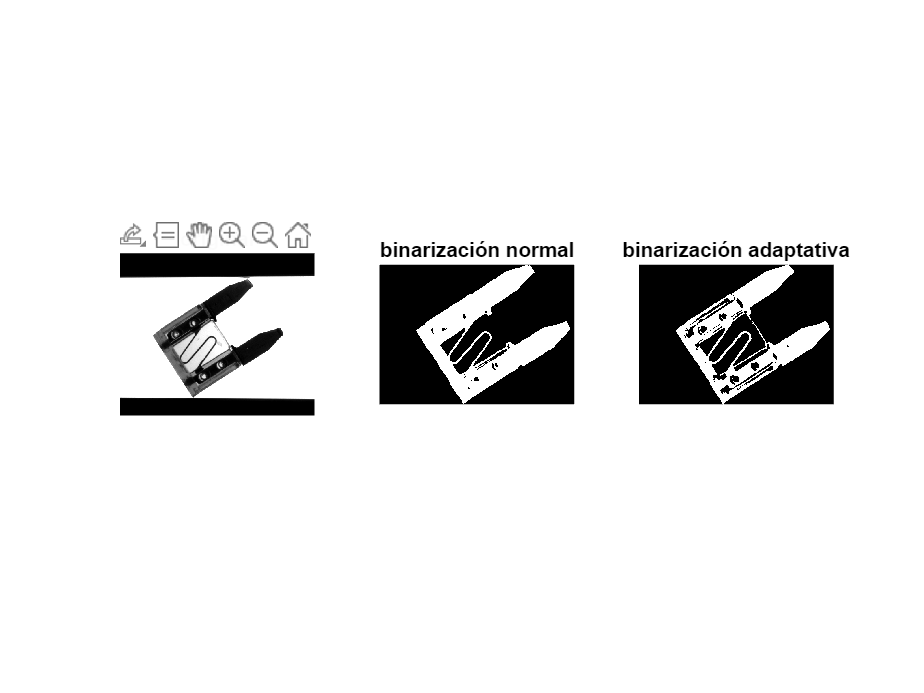

figure;
i=15;
img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
imgc = imcrop(img, ROI);
imgf = real(ifft2(fft2(imgc) .* fftshift(ILPF))/255);
subplot(131); imshow(img);title("original");
subplot(132); imshow(1-imbinarize(imgf));title("binarización normal");
subplot(133); imshow(1-imbinarize(imgf,'adaptive', Sensitivity=0.75));title("binarización adaptativa");

Aplicamos la binarización a todas las imágenes y comprobamos que no hemos perdido información relevante

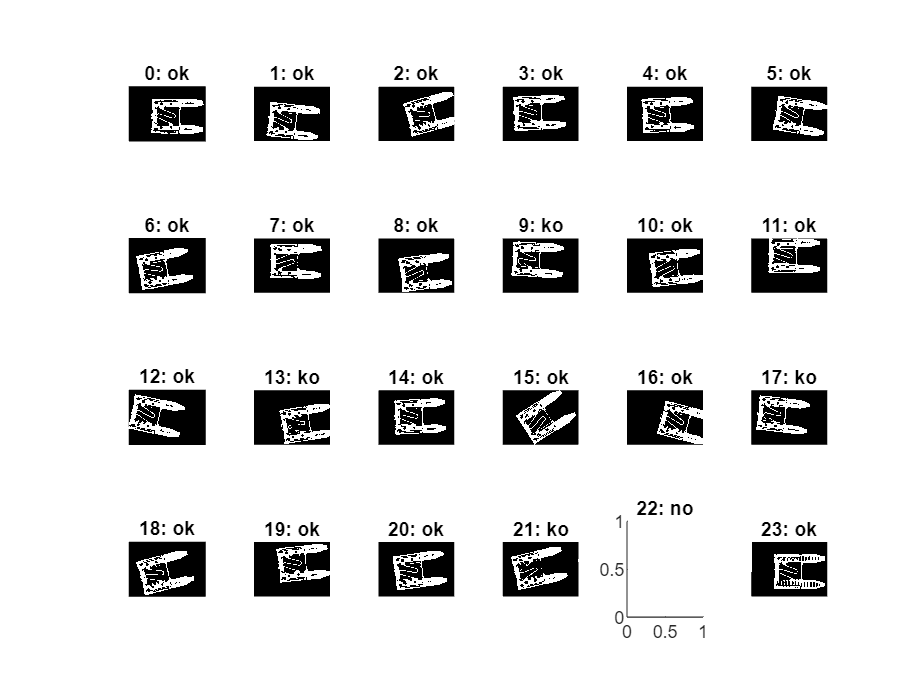

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        imgc = imcrop(img, ROI);
        imgf = real(ifft2(fft2(imgc) .* fftshift(ILPF))/255);
        imshow(1-imbinarize(imgf,'adaptive', Sensitivity=0.75));
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));
end

### 6 Aplicacción de operadores morfológicos

Probamos a mejorar las imágenes con operadores morfológicos

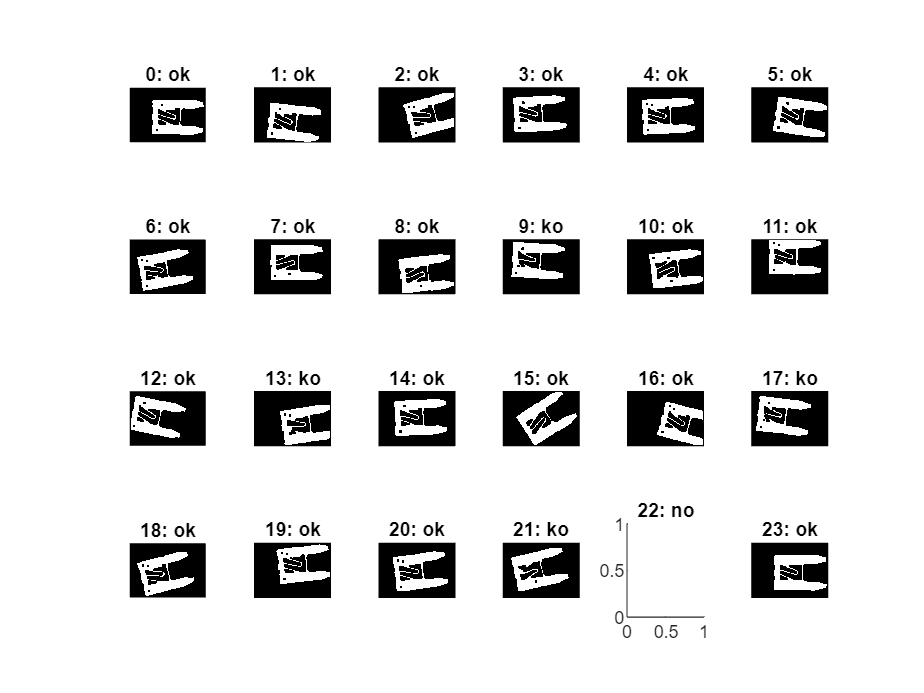

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        img = imcrop(img, ROI);
        imgf = real(ifft2(fft2(img) .* fftshift(ILPF))/255);
        imgb = 1-imbinarize(imgf,'adaptive', Sensitivity=0.70);
        %imgm = bwmorph(imgb, 'open');
        imgm = bwmorph(imgb, 'dilate', 5);
        imgm = bwmorph(imgm, 'erode', 5);
        imshow(imgm);
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));
end

### Extracción de descriptores

Invertimos la imagen resultante y obtenemos las regiones conectadas

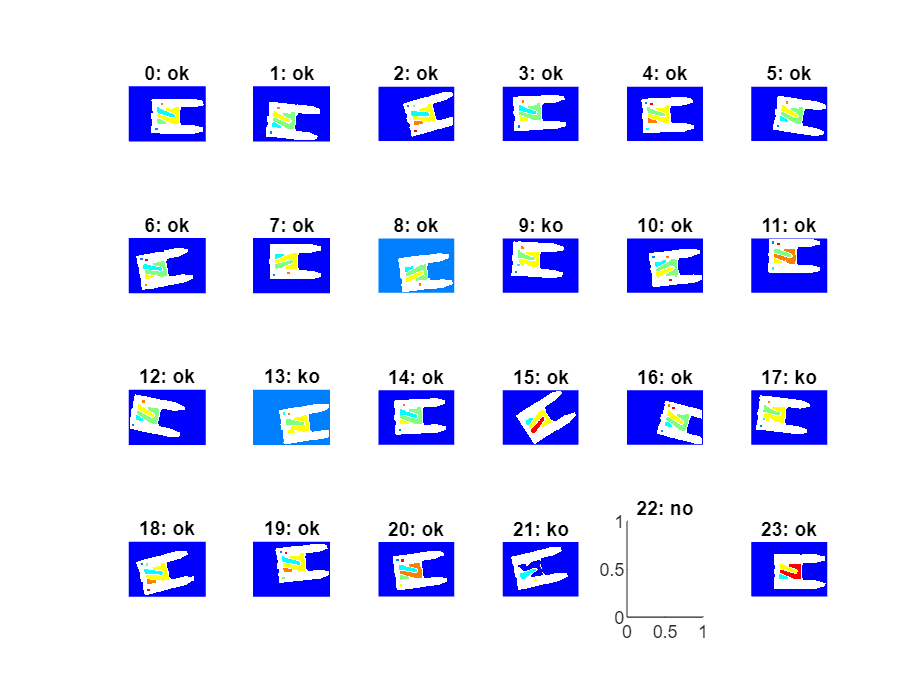

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        img = imcrop(img, ROI);
        imgf = real(ifft2(fft2(img) .* fftshift(ILPF))/255);
        imgb = 1-imbinarize(imgf,'adaptive', Sensitivity=0.70);
        %imgm = bwmorph(imgb, 'open');
        imgm = bwmorph(imgb, 'dilate', 5);
        imgm = bwmorph(imgm, 'erode', 5);
        imshow(label2rgb(bwlabel((1-imgm))));
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));
end

Observamos que cuando el fusible es correcto, tiene que haber 3 superficies (aparte del fondo) con un área significtivamente mayor que el área de los huecos circulares. En el peor caso, la superficie más pequeña de la zona del fusible tiene 763 pixeles.

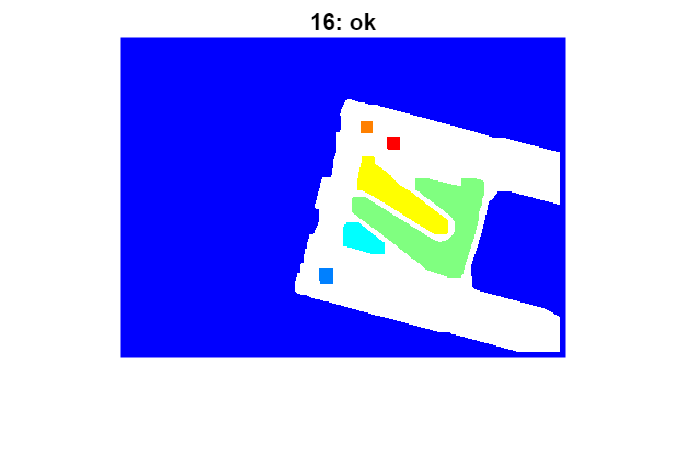

figure
i=16;
img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
img = imcrop(img, ROI);
imgf = real(ifft2(fft2(img) .* fftshift(ILPF))/255);
imgb = 1-imbinarize(imgf,'adaptive', Sensitivity=0.70);
imgm = bwmorph(imgb, 'dilate', 5);
imgm = bwmorph(imgm, 'erode', 5);
imgl=bwlabel((1-imgm));
imshow(label2rgb(imgl));
title(sprintf("%d: %s", i, titulos(estados(i+1),:)));

pro = regionprops (imgl,'Area');
pro.Area

ans = 83838

ans = 179

ans = 763

ans = 4981

ans = 2120

ans = 121

ans = 143

Por tanto, usamos como criterio de clasificación el número de regiones con un área de más de 700 pixeles, que debe ser igual a 4 para que el fusible sea correcto

sum([pro.Area]>700)

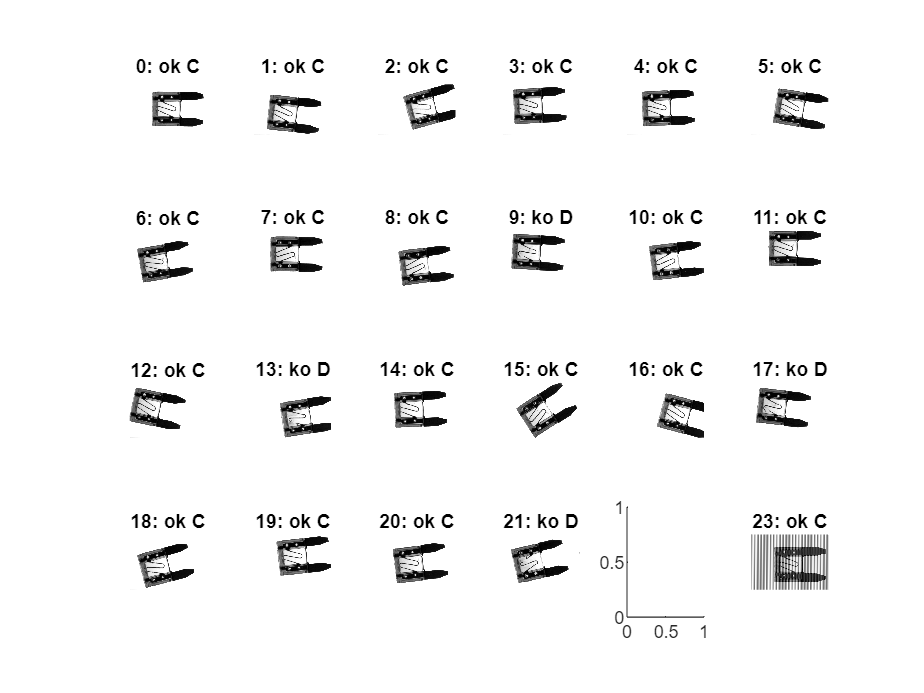

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        img = imcrop(img, ROI);
        imgf = real(ifft2(fft2(img) .* fftshift(ILPF))/255);
        imgb = 1-imbinarize(imgf,'adaptive', Sensitivity=0.70);
        %imgm = bwmorph(imgb, 'open');
        imgm = bwmorph(imgb, 'dilate', 5);
        imgm = bwmorph(imgm, 'erode', 5);
        imgl=bwlabel((1-imgm));
        pro = regionprops (imgl,'Area');
        imshow(img);
        if (sum([pro.Area]>700) == 4)
            title(sprintf("%d: %s C", i, titulos(estados(i+1),:))); % CORRECTO
        else
            title(sprintf("%d: %s D", i, titulos(estados(i+1),:))); % DEFECTO
        end
    end
end

# Código deshechado

Calculamos el número de Euler para cada imagen

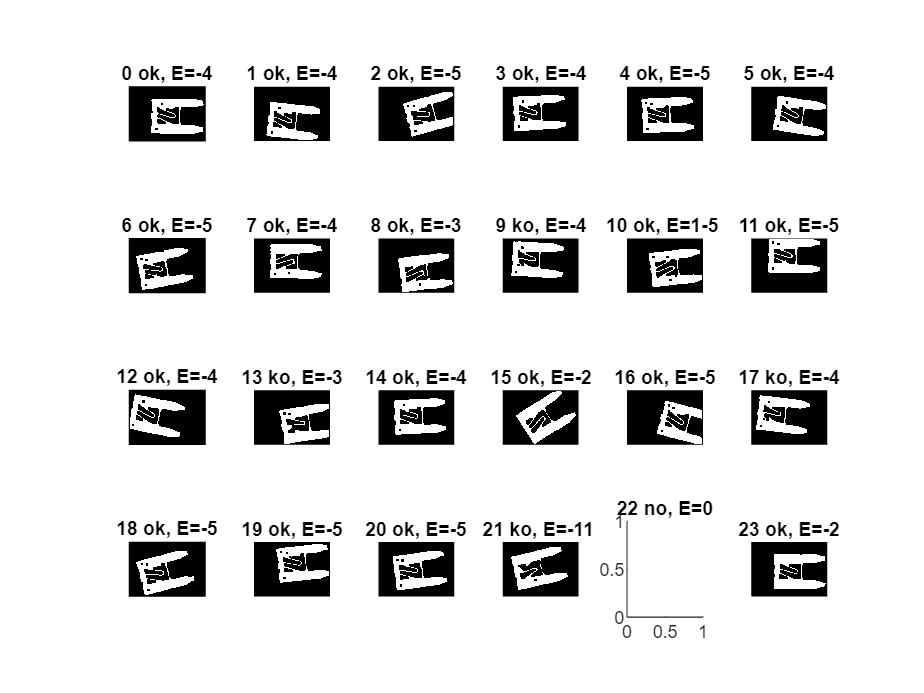

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        imgc = imcrop(img, ROI);
        imgf = real(ifft2(fft2(imgc) .* fftshift(ILPF))/255);
        imgb = 1-imbinarize(imgf,'adaptive', Sensitivity=0.70);
        imgm = bwmorph(imgb, 'dilate', 5);
        imgm = bwmorph(imgm, 'erode', 5);
        imgm = bwmorph(imgm, 'close');
        imshow(imgm);
        props = regionprops (imgm,'EulerNumber');
        title(sprintf("%d %s, E=%d", i, titulos(estados(i+1),:), props.EulerNumber));
    else
        title(sprintf("%d %s, E=%d", i, titulos(estados(i+1),:), 0));
    end 
end

# pruebas

#### Filtrado en dominio espacial

Las imágenes muestran sombras que hay que intentar eliminar

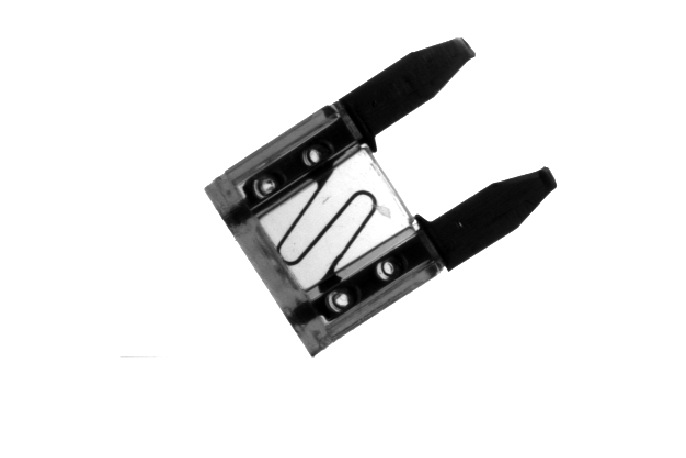

i = 15;
img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
img = imcrop(img, ROI);
figure;
imshow(img);

Probamos con distintas opciones de filtro, pero ninguna quita realmente las "manchas" que se aprecian

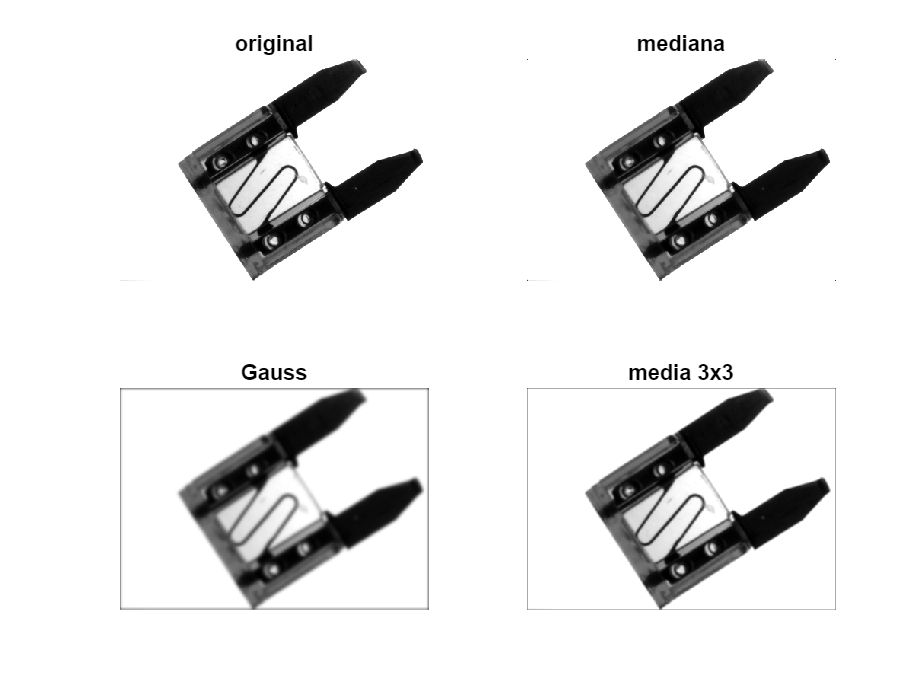

figure
subplot(2,2,1); imshow(img); title('original');
subplot(2,2,2); imshow(medfilt2(img)); title('mediana');
hsize = 11; sigma=2;
fgauss = fspecial ('gaussian', hsize, sigma);
subplot(2,2,3); imshow(conv2(img, fgauss, 'same')/255); title("Gauss");
m3x3=ones(3,3)/(3*3);
subplot(2,2,4); imshow(conv2(img, m3x3, 'same')/255); title("media 3x3");

#### Realce

En lugar de aplicar un filtro, probamos a realzar las imágenes con el histograma de la mejor que tenemos (p. ej. la 18);

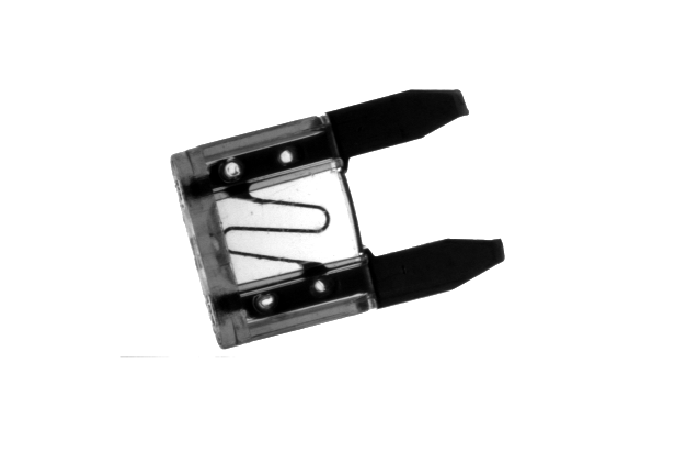

i = 18;
img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
img = imcrop(img, ROI);
figure;
imshow(img);

Utilizamos el histograma especificado de la imagen 18 para mejorar la imagen 6

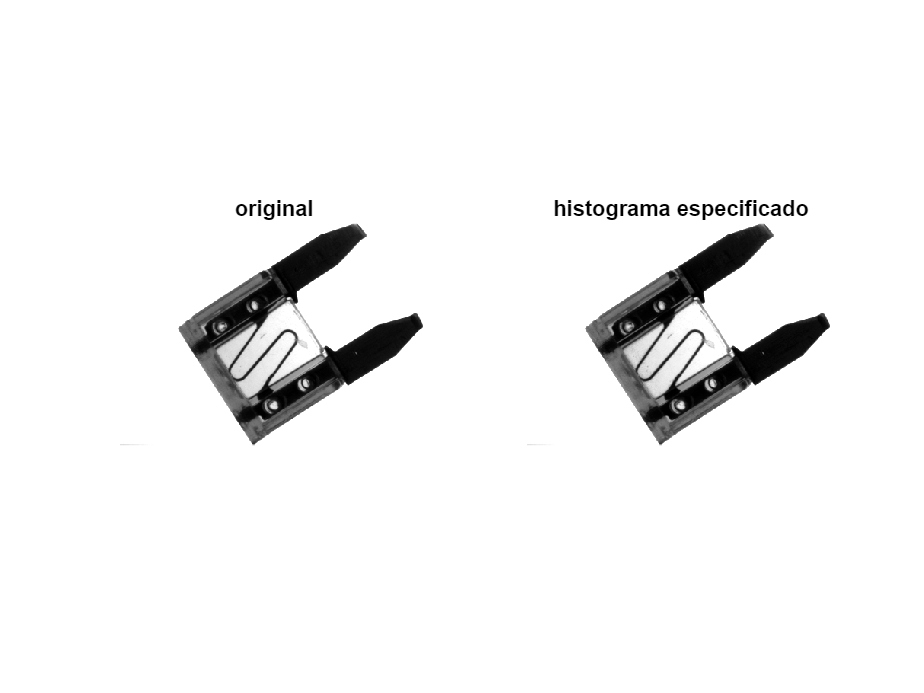

hist_spec = imhist(img);
%lut_spec =  uint8 (cumsum(imhist(im17)/numel(im17))*255);
i = 15;
img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
img = imcrop(img, ROI);
figure;
subplot(1,2,1); imshow(img);title('original');
subplot(1,2,2); imshow(histeq(img, hist_spec));title('histograma especificado');

figure;
i=15;
img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
imgc = imcrop(img, ROI);



d0 = 80; % frecuencia de corte
n = 1; % orden del filtro;
[tamx,tamy] = size(imgc); % Tamaño de la imagen
[xx,yy] = meshgrid(1:tamx,1:tamy);

d = sqrt((xx-tamx/2).^2+(yy-tamy/2).^2); % Distancia al centro
ILPF = (d < d0)';

d = sqrt((xx-tamx/2).^2+(yy-tamy/2).^2); % Distancia al centro
BLPF = (1./(1+(d/d0).^(2*n)))';
%imgf = imgc; 
imgf = real(ifft2(fft2(imgc) .* fftshift(ILPF))/255);
%imgf = real(ifft2(fft2(imgc) .* fftshift(BLPF))/255);


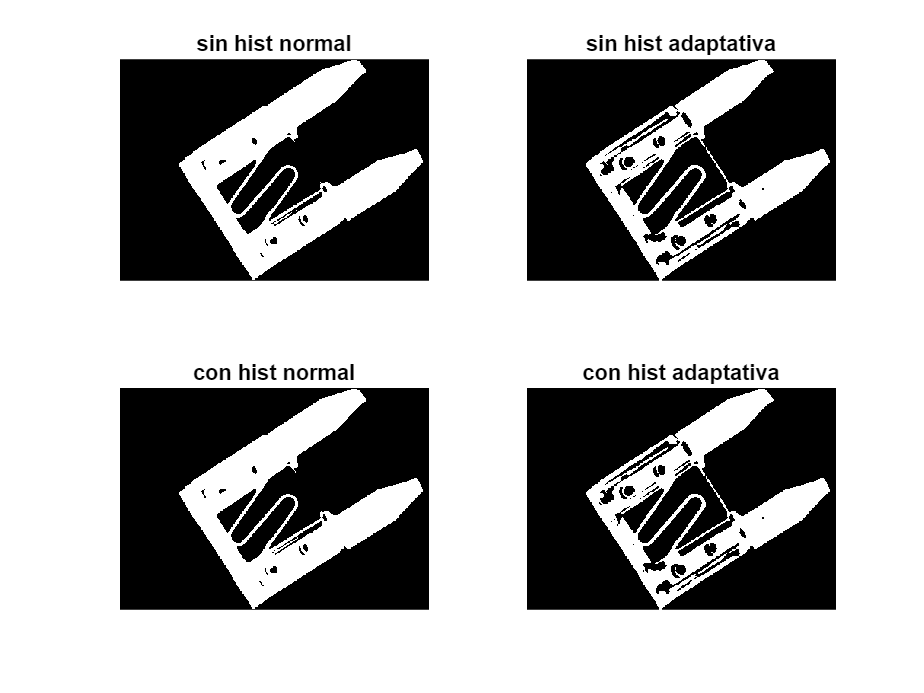


imgh = histeq(imgf, hist_spec);
subplot(221); imshow(1-imbinarize(imgf));title("sin hist normal");
subplot(222); imshow(1-imbinarize(imgf,'adaptive', Sensitivity=0.75));title("sin hist adaptativa");
subplot(223); imshow(1-imbinarize(imgh));title("con hist normal");
subplot(224); imshow(1-imbinarize(imgh,'adaptive', Sensitivity=0.75));title("con hist adaptativa");

#### Umbralización adaptativa

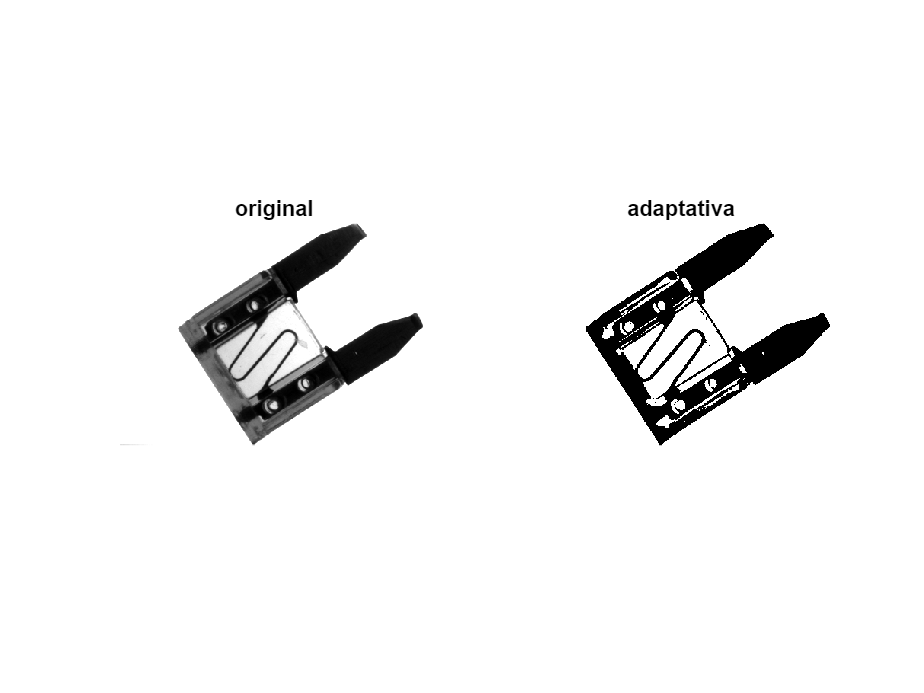

i = 15;
img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
img = imcrop(img, ROI);
figure;
subplot(1,2,1); imshow(img);title('original');
subplot(1,2,2); imshow(imbinarize(img, 'adaptive', Sensitivity=0.7));title('adaptativa');